`mu.boxplot` Function Demo

This Live Script demonstrates the usage of the `mu.boxplot` function, a highly customizable grouped boxplot tool for complex experimental designs.

Generate Sample Data:

% Let's create two groups, each with 3 categories, of varying data sizes.
rng(30);  % for reproducibility
group1 = [randn(50,1), randn(50,1)+1, randn(50,1)+2];
group2 = [randn(60,1), randn(60,1)+1, randn(60,1)+2.5];

X = {group1, group2};

Basic Usage

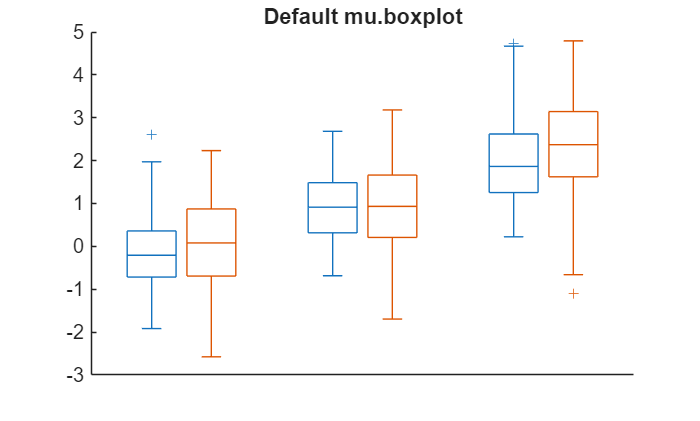

% Draw a simple grouped boxplot with default settings.
figure;
mu.boxplot(X);
title('Default mu.boxplot');

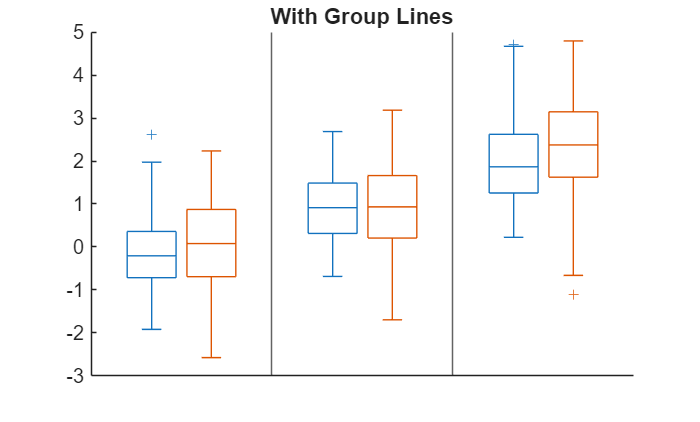

% Add group lines
figure;
mu.boxplot(X, 'GroupLines', true);
title('With Group Lines');

Notch Boxplot

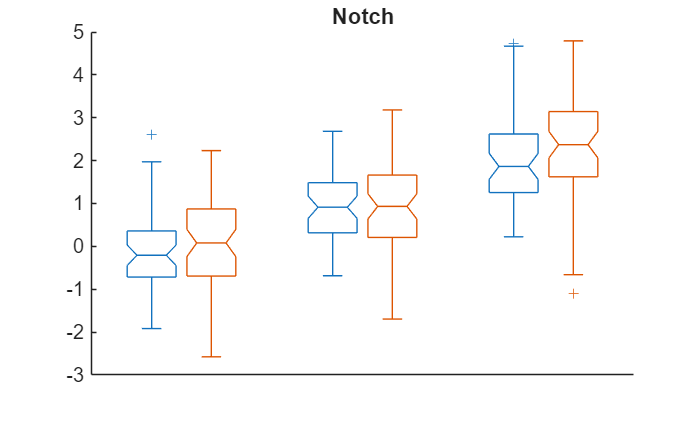

figure;
mu.boxplot(X, 'Notch', 'on');
title('Notch');

Customized Group and Category Labels

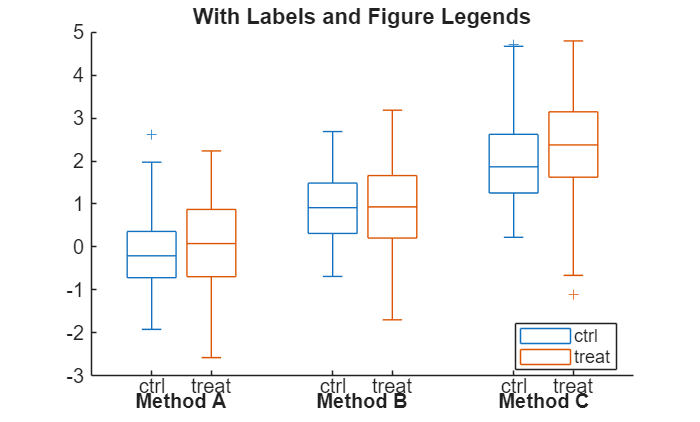

% Add descriptive labels and color the groups differently.
figure;
mu.boxplot(X, ...
    'GroupLabels', {'ctrl', 'treat'}, ...
    'GroupLegends', {'ctrl', 'treat'}, ...
    'CategoryLabels', {'Method A', 'Method B', 'Method C'});
title('With Labels and Figure Legends');

 Adjust Jitter data points and Whisker

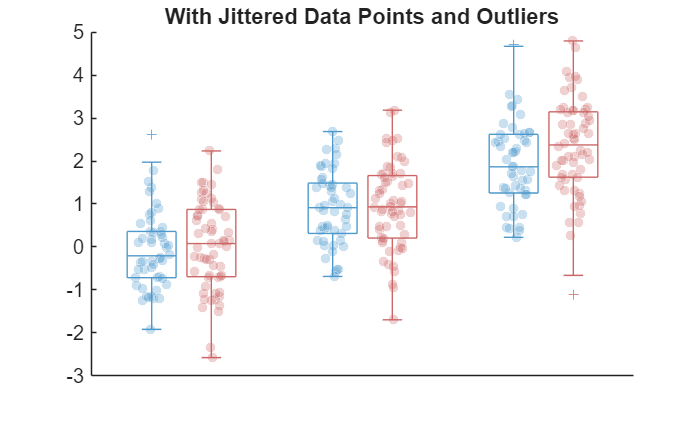

% Show individual data points with jitter and visible outliers.
figure;
mu.boxplot(X, ...
    'IndividualDataPoint', 'show', ...
    'Outlier', 'show', ...
    'Jitter', 0.2, ...
    'Colors', [0.3 0.6 0.8; 0.8 0.4 0.4]);
title('With Jittered Data Points and Outliers');

Custom Box and Symbol Appearance

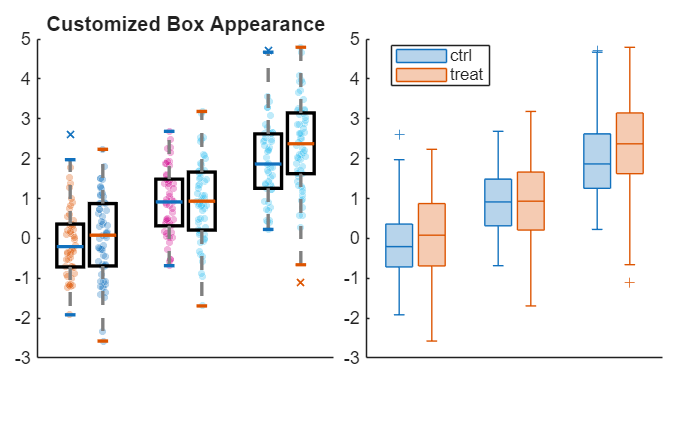

% Control box edge color, line width, symbol size, and more.
figure;
mu.subplot(1, 2, 1);
mu.boxplot(X, ...
    'BoxParameters', {'EdgeColor', 'k', 'LineWidth', 2}, ...
    'IndividualDataPoint', 'show', ...
    'SymbolParameters', {'SizeData', 20, 'MarkerFaceColor', 'flat'}, ...
    'WhiskerParameters', {'LineStyle', '--', 'Color', [0.5 0.5 0.5]}, ...
    'OutlierParameters', {'Marker', 'x', 'LineWidth', 1});
title('Customized Box Appearance');

mu.subplot(1, 2, 2);
mu.boxplot(X, ...
    'GroupLegends', {'ctrl', 'treat'}, ...
    'BoxParameters', {'FaceColor', 'auto', 'FaceAlpha', 0.3});

Different Center Line and Error Type (Mean ± Standard Deviation) and Whiskers

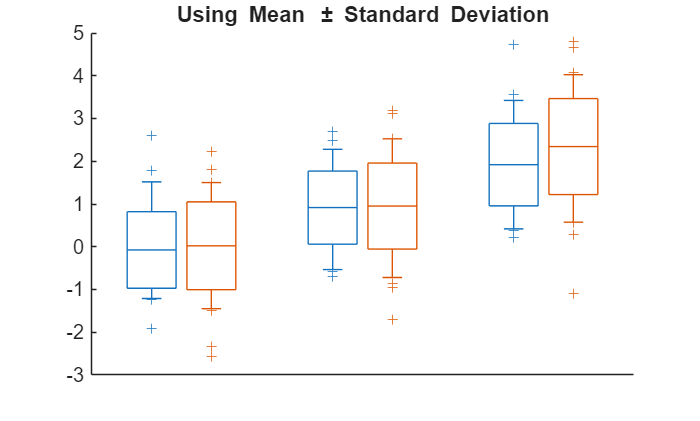

figure;
mu.boxplot(X, ...
    'BoxEdgeType', 'STD', ...
    'CenterLineParameters', {'Type', 'Mean'}, ...
    'Whisker', [5, 95]);
title('Using Mean \pm Standard Deviation');

Notes

-  This function supports hierarchical axis labeling.

-  Use `'GroupSpace'` and `'CategorySpace'` to control horizontal spacing.

-  Clipping is ON by default. Turn it off if jittered points are cut off.

-  Use returned `res` struct to access median, whisker, etc.

 See `help mu.boxplot` for full parameter list.